# 1222第十六次上机练习

**1.** 设f = t2, g = sin(2π t)

    a) 将f绘制为黑线，g绘制为一系列红色圆圈，t的范围从1到2微秒，绘制在同一张图上，标明每个轴，加标题和图例。

    b) 调整上述绘图的线段宽度为2.5，并将圆圈涂满蓝色

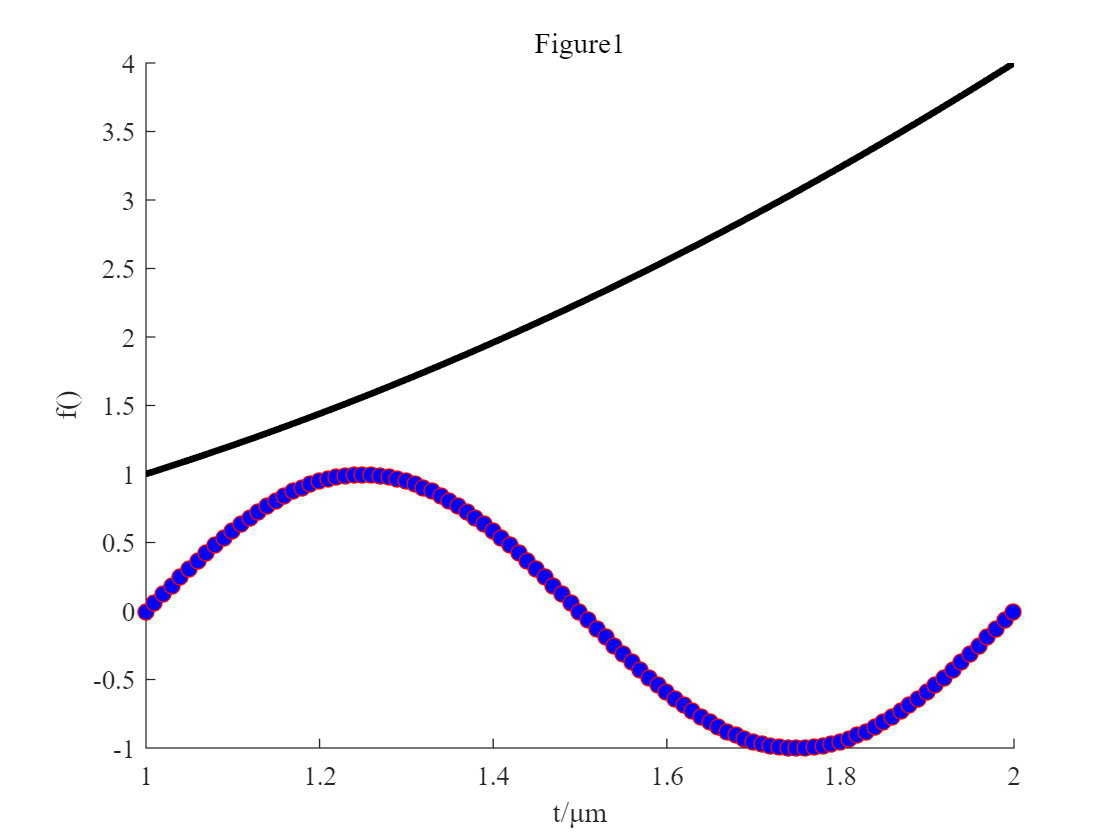

close all;
t = 1:0.01:2;
f = t.^2;
g = sin(2*pi*t);
hold on;
plot(t,f,'Color','Black','LineWidth',2.5);
plot(t,g,'Color','Red','Marker','o','MarkerFaceColor','blue');
xlabel('t/μm');ylabel('f()');
set(gca,'FontName','Times New Roman');
title('Figure1');
hold off;

**2.** 使用MATLAB的subplot绘制下列图像

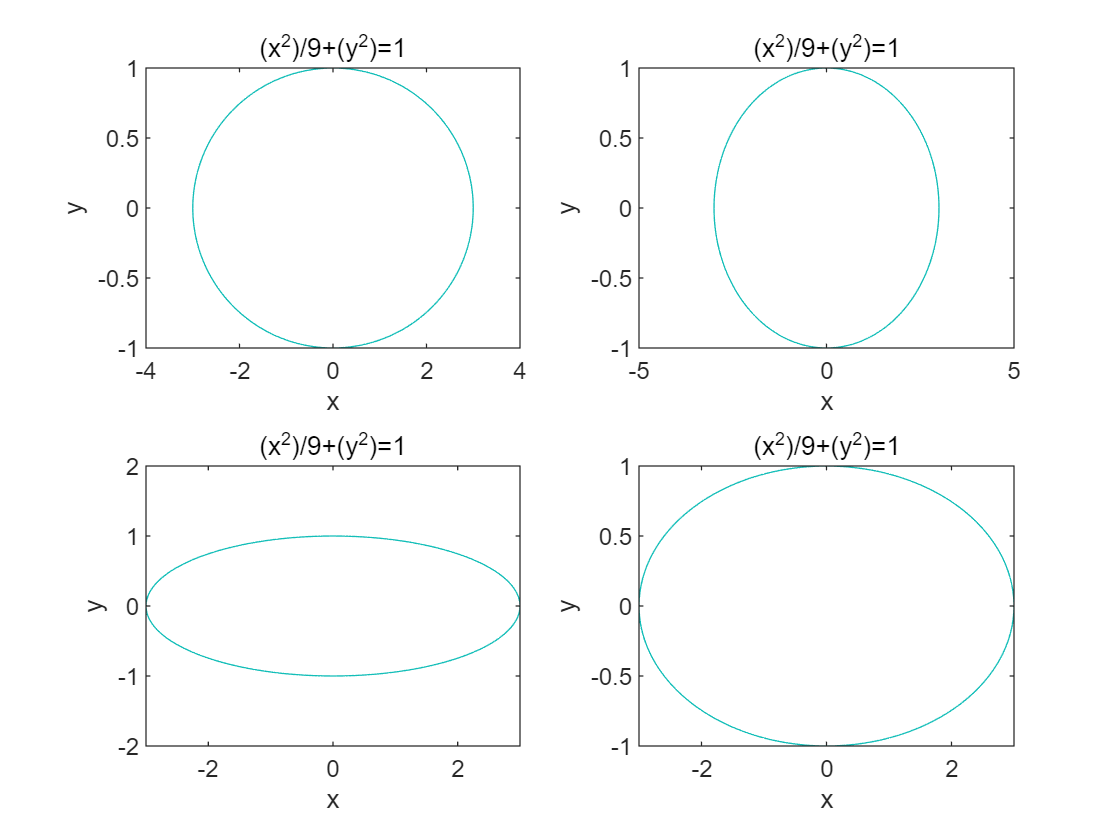

close all;
subplot(2,2,1);
ezplot('(x^2)/9+(y^2)=1');
xlim([-4,4]);ylim([-1,1]);
subplot(2,2,2);
ezplot('(x^2)/9+(y^2)=1');
xlim([-5,5]);ylim([-1,1]);
subplot(2,2,3);
ezplot('(x^2)/9+(y^2)=1');
xlim([-3,3]);ylim([-2,2]);
subplot(2,2,4);
ezplot('(x^2)/9+(y^2)=1');
xlim([-3,3]);ylim([-1,1]);

**3. **绘制*y* = sin(*x*)，其中x在[0, pi/50, 2pi]，显示*y*的曲线, 绘制*y* = cos(*x*)，其中x在[0, pi/50, 2pi]，显示*y*的曲线

    a) 在同一张figure中展示上述两个曲线

    b) 将sin曲线的宽度设置为2，颜色设置为红色，将cos曲线设置为虚线，颜色为蓝色

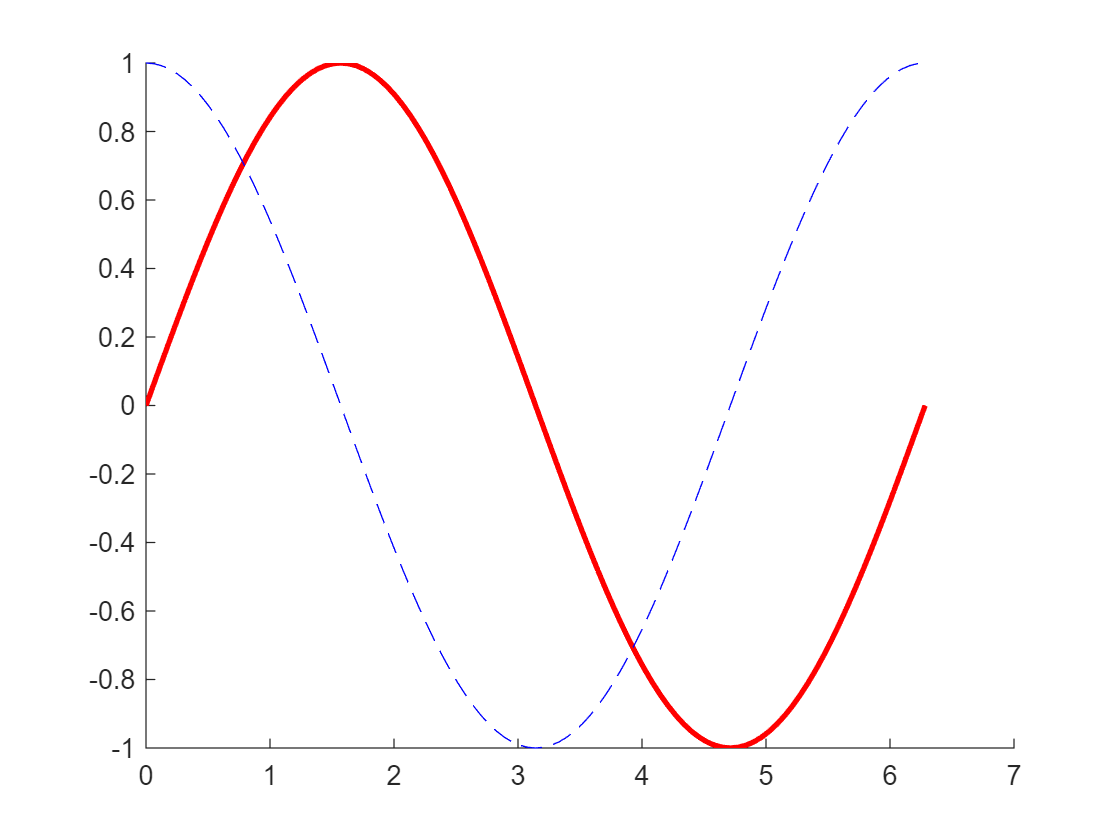

close all;
x = 0:pi/50:2*pi;
y1 = sin(x);
y2 = cos(x);
hold on;
line(x,y1,'LineWidth',2,'Color','Red');
line(x,y2,'LineStyle','--','Color','blue');

**4. **在同一张figure上绘制三条不同的曲线y = sin(x)，y = sin(x – 0.1)，y = sin(x-0.2)，其中x在[0, pi/50, 2pi]，要求使用不同的图例和颜色(可自拟)，在figure上添加legend，横、纵坐标以及标题。再将上述三条曲线分别绘制到三张子图中(使用subplot)

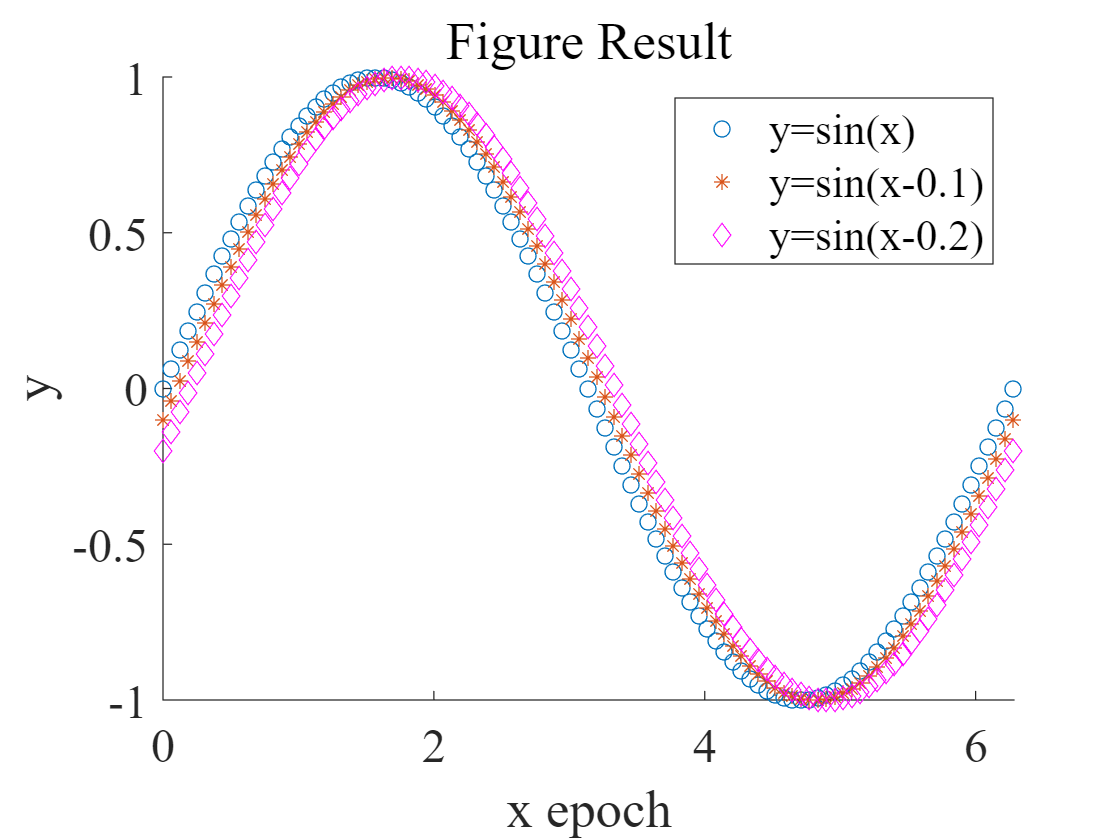

% (1)
close all;
x = 0:pi/50:2*pi;
y1 = sin(x);
y2 = sin(x-0.1);
y3 = sin(x-0.2);
hold on;
plot(x,y1,'o');
plot(x,y2,'*');
plot(x,y3,'md');
legend('y=sin(x)','y=sin(x-0.1)','y=sin(x-0.2)');
xlabel('x epoch');
ylabel('y');
set(gca,'FontName','Times New Roman','FontSize',18);
title('Figure Result');
hold off;

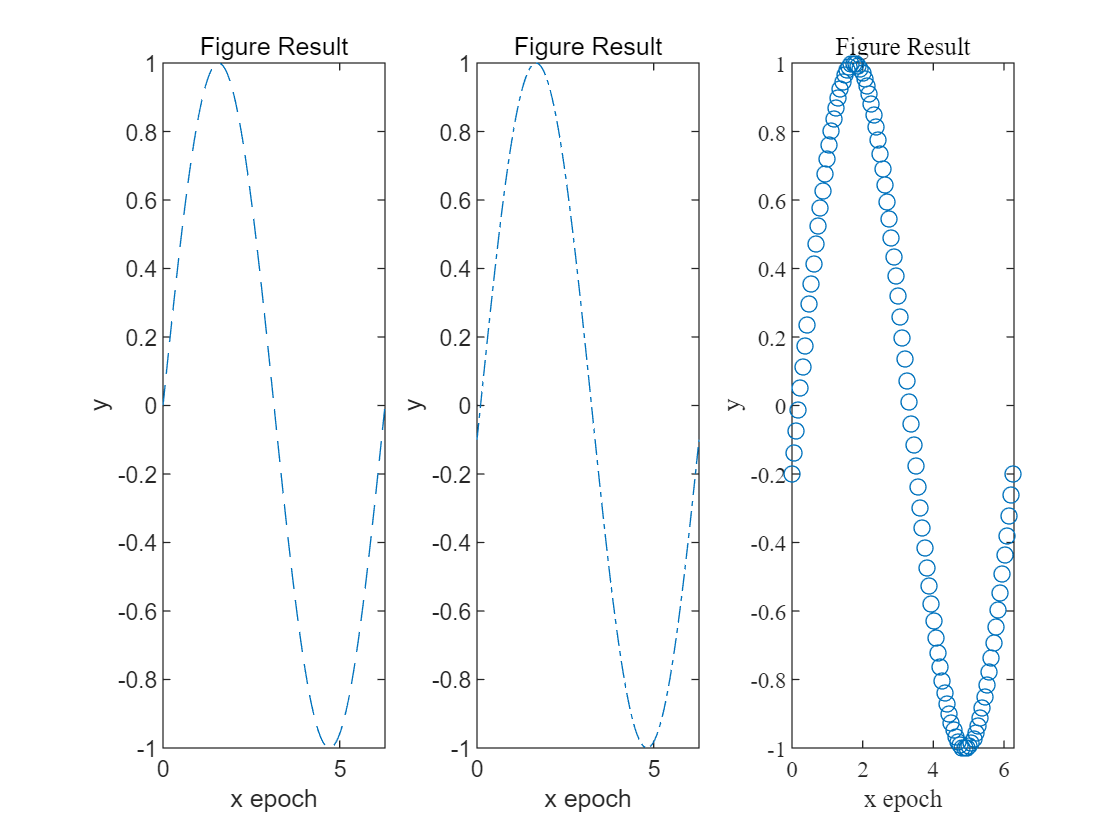

% (2)
close all;
subplot(1,3,1);
x = 0:pi/50:2*pi;
y1 = sin(x);
y2 = sin(x-0.1);
y3 = sin(x-0.2);
plot(x,y1,'--');
title('Figure Result');
xlabel('x epoch');
ylabel('y');
subplot(1,3,2);
plot(x,y2,'-.');
title('Figure Result');
xlabel('x epoch');
ylabel('y');
subplot(1,3,3);
plot(x,y3,'o');
set(gca,'FontName','Times New Roman');
title('Figure Result');
xlabel('x epoch');
ylabel('y');

**5.** 绘制曲线y = sin(x)，其中x在[0, pi/50, 2pi]，修改图片的横坐标刻度，使pi正确显示，使用marker将图形中的数据点加粗显示，修改图上的字体，设置字号为16，字体为Times New Roman

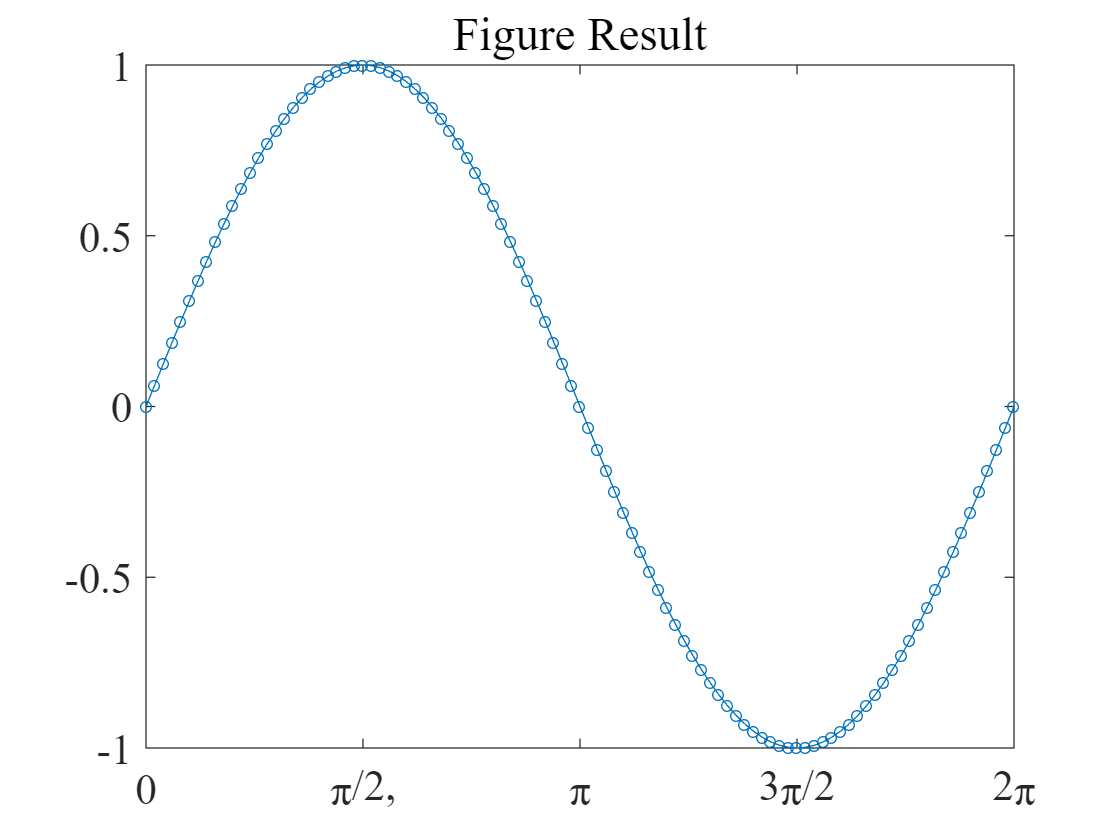

close all;
x = 0:pi/50:2*pi;
y = sin(x);
plot(x,y,'Marker','o','MarkerSize',4);
set(gca,'FontName','Times New Roman','FontSize',16);
set(gca,'XTick',0:pi/2:2*pi)
set(gca,'XTickLabel', {'0','\pi/2,','\pi','3\pi/2','2\pi'});
title('Figure Result');

**6.** x = [1 2 5 4 8]; y = [x;1:5]，绘制一个堆叠的水平条形图

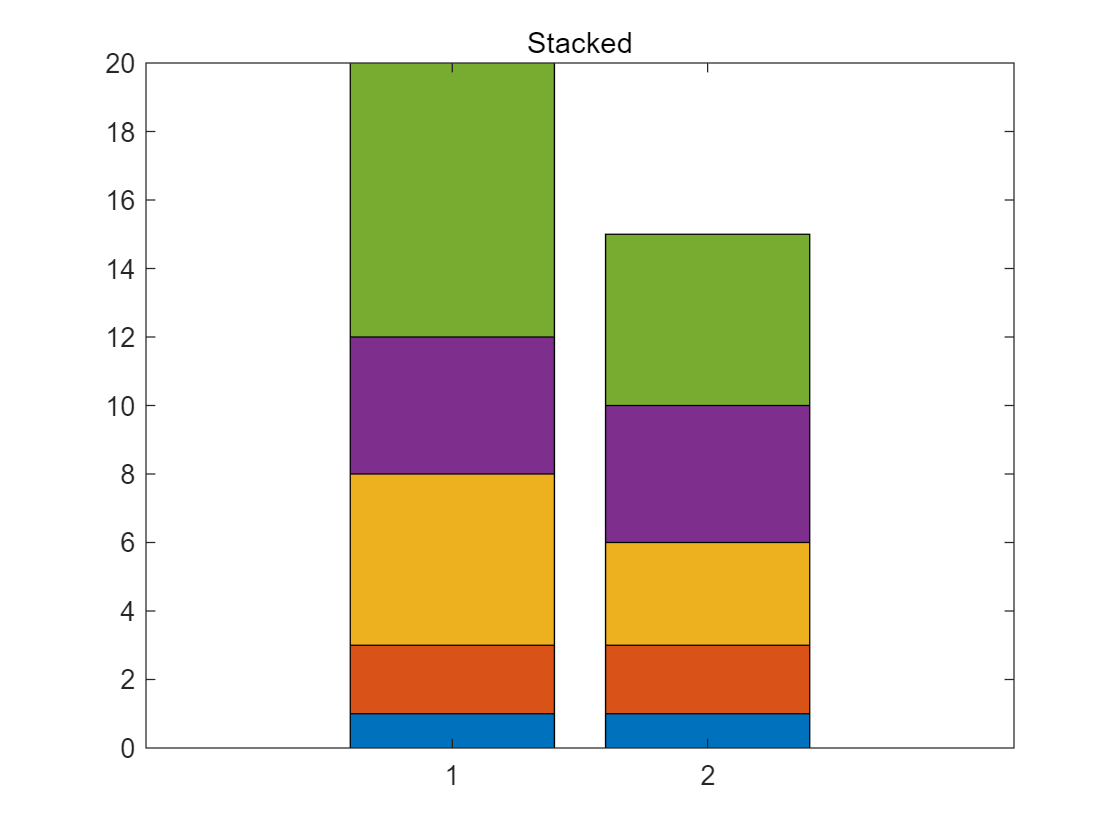

close all;
x = [1,2,5,4,8];
y = [x;1:5];
bar(y,'stacked');
title('Stacked');

**7.** 绘制函数

并且使用stem()加上以5Hz采样的点

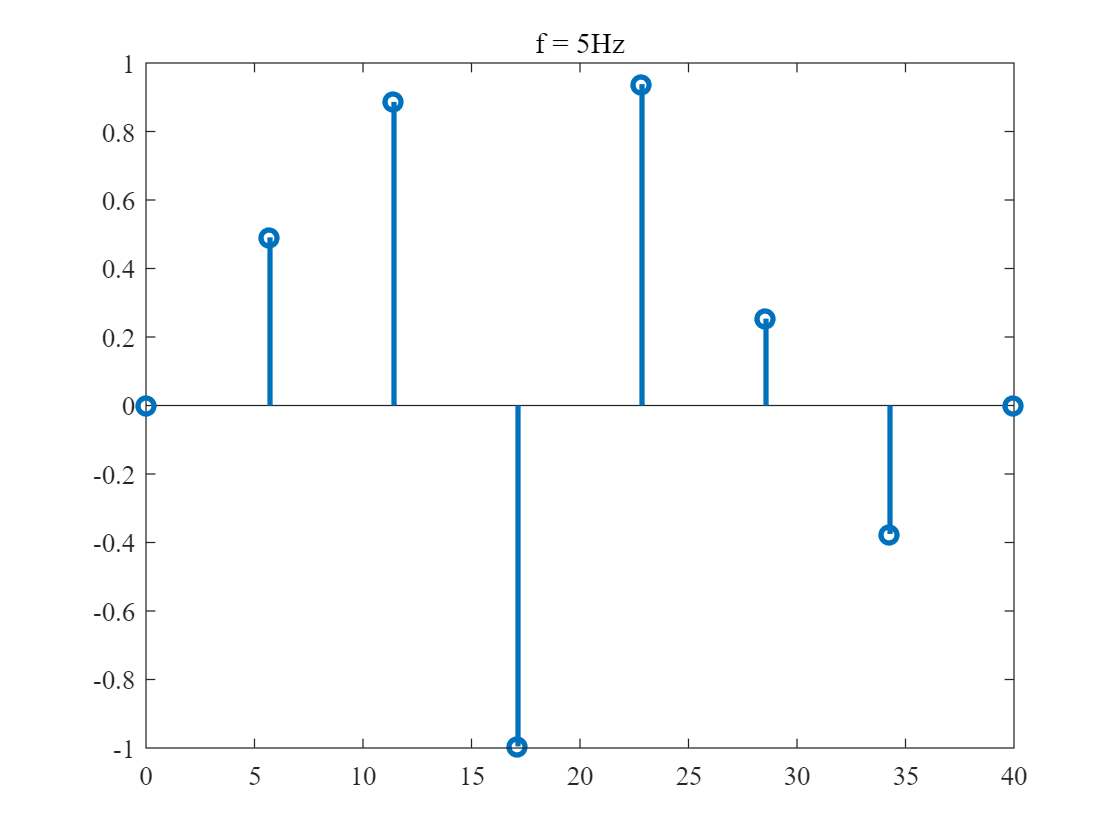

close all;
x = linspace(0,40,8);
y = sin(pi*(x.^2)/4);

stem(x,y,"LineWidth",2);
title('f = 5Hz');
set(gca,'FontName','Times New Roman');

**8. **G = [46 38 29 24 13]; S = [29 27 17 26 8]; B = [29 23 19 32 7]

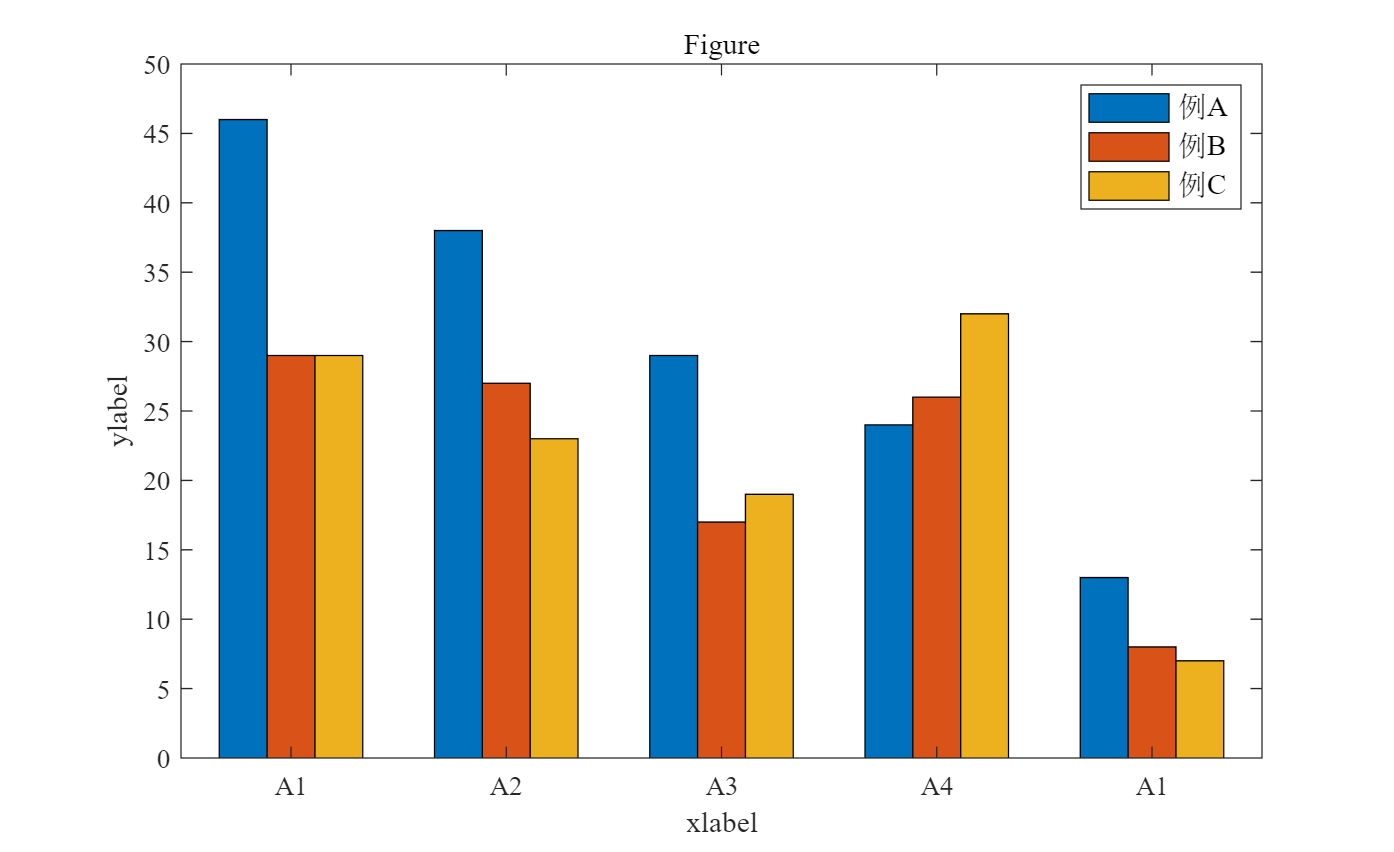

close all;
G = [46 38 29 24 13]; S = [29 27 17 26 8]; B = [29 23 19 32 7];
figure('position',[150,100,900,550])%确定图片的位置和大小，[x y width height]
%准备数据
Y = [];
for i = 1:5
    Y = [Y;G(i),S(i),B(i)];
end
X=1:5;
 %画出4组柱状图，宽度1
h=bar(X,Y,1);      
 %修改横坐标名称、字体
set(gca,'XTickLabel',{'A1','A2','A3','A4'},'FontSize',10,'FontName','Times New Roman');
title('Figure');
xlabel('xlabel');ylabel('ylabel');
legend({'\fontname{宋体}例\fontname{Times New Roman}A','\fontname{宋体}例\fontname{Times New Roman}B','\fontname{宋体}例\fontname{Times New Roman}C','\fontname{宋体}例\fontname{Times New Roman}D'},'FontSize',11);